# Modal Analysis of Soft Robot

#### Import all relevant files and build matrices

clear vars; close all; clc;

num_nodes = 1628;
sim_length = 300;

% (Mass) M - Constant mass matrix
% (Stiffness) K - K(q_g) where q_g is resting eq under gravity
% (Damping) DAMP - alpha * M + beta * K (where alpha = 2.5, beta = 0.01)
% (Constraint matrix) H - H(q_g) is the input constraint/selection matrix
alpha = 2.5;
beta = 0.01;
M = readmatrix("../M_actual.csv");
K = readmatrix("../K_actual.csv");
DAMP = alpha.*M + beta.*K;
H = readmatrix("../H_actual.csv");

% Recall: format of x is x = (v, q)
% This is the output configuration for figure 8!
% UNCOMMENT THIS IF YOU WANT TO SEE AMPLITUDES OF FIGURE 8
%vq_figureeight = readmatrix("../vq.csv").';
%q_figureeight = vq_figureeight(3*num_nodes+1:end, sim_length:end);
t_span = linspace(0, 10, 1002);

% Build C (output matrix)
output_node = 1354;
C = zeros(3, 3 * num_nodes);
C(1, 3*output_node + 1) = 1;
C(2, 3*output_node + 2) = 1;
C(3, 3*output_node + 3) = 1;

**Compute (undamped) modes**

Nmax = 50;
[PSI, lams] = eigs(M \ K, Nmax, 'smallestabs');
wn = sqrt(diag(lams));

**Load decaying trajectories**

% mode_0 \in [1, 2, 3, 12, 13, 23]. Represents the linear combination of
% modes desired at initial condition. 
prompt = "Select modal displacement in [1, 2, 3, 12, 13, 23] (e.g. 12 is initial displacement of robot along modes 1 + 2): ";
prompt = prompt + "Options: \n";
prompt = prompt +  "1 - displacement along positive mode 1 \n";
prompt = prompt + "2 - displacement along positive mode 2 \n";
prompt = prompt + "3 - displacement along NEGATIVE mode 3 \n";
prompt = prompt + "12 - displacement along positive mode 1 and positive mode 2 \n";
prompt = prompt + "13 - displacement along positive mode 1 and and positive mode 3 \n";
prompt = prompt + "23 - displacement along positive mode 2 and NEGATIVE 3 \n";
prompt = prompt + "Select integer: ";
mode_initial_condition = input(prompt);

% q_0 is initial modal displacement
num_modes = 3;
decay_filename = sprintf('mode%d_decay.csv', mode_initial_condition);
q0_decay_trajectory = readmatrix(decay_filename).';

% v_0 is initial modal velocity
decay_vel_filename = sprintf('mode%d_decay_velocity.csv', mode_initial_condition);
v0_decay_trajectory = readmatrix(decay_vel_filename).';

**Plot decaying trajectories for selected initial condition**

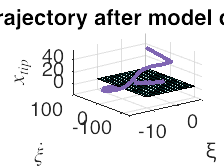

% Compute change of basis to modal coordinates of displacement and velocity
% trajectories
PHI = PSI(:, 1:3);
q_tilde_actual = pinv(PHI) * q0_decay_trajectory;
v_tilde_actual = pinv(PHI) * v0_decay_trajectory;

% Retrieve configuration trajectory of tip node
q_out = C * q0_decay_trajectory;

% Plot x trajectory of tip node onto SSM tangent to mode 1
% q_out(i,:), where i = 1 is x, i = 2 is y, and i = 3 is z

prompt2 = "Which modal subspace would you like to visualize convergence to? \n";
prompt2 = prompt2 + "Options: \n";
prompt2 = prompt2 + "1 - (\xi_1, \dot{xi}_1) \n";
prompt2 = prompt2 + "2 - (\xi_2, \dot{xi}_2) \n";
prompt2 = prompt2 + "3 - (\xi_3, \dot{xi}_3) \n";
prompt2 = prompt2 + "Select Integer: ";
mode_span = input(prompt2);

fig = figure();
set(fig,'defaultLegendAutoUpdate','off');

plot3(q_tilde_actual(mode_span,:), v_tilde_actual(mode_span,:), q_out(1,:), 'LineWidth',2.0, 'Color', [.5 .4 .7])
hold on;
xlabel('\xi'); ylabel('$\dot{\xi}$', 'interpreter','latex'); zlabel('$x_{tip}$', 'interpreter','latex');

title_string = sprintf("Decay trajectory onto 2-D subspace spanned by mode %d", mode_span);
title('Decay trajectory after model displacement')
grid on;

% % Plot x-y plane for easier visualization
basis_1 = -5:.5:5;
basis_2 = -100:10:100;

[X,Y] = meshgrid(basis_1, basis_2);
Z = zeros(size(X, 1));
surf(X,Y,Z);
alpha 0.2

**Plot Amplitudes of Trajectory in Modal Coords**

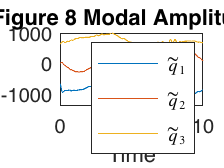

xi_eightshape_traj = pinv(PHI) * q_figureeight;
figure;
plot(t_span, xi_eightshape_traj(1, 1:end-1));
hold on;
plot(t_span, xi_eightshape_traj(2, 1:end-1));
hold on;
plot(t_span, xi_eightshape_traj(3, 1:end-1));
title('Figure 8 Modal Amplitudes');
xlabel('Time'); 
xlim([0,10])
h = legend('$\tilde{q}_1$', '$\tilde{q}_2$', '$\tilde{q}_3$');
h.Interpreter = 'latex';